## **Calculus II**

### **Hiroyuki Chihara (University of the Ryukyus, Okinawa Island, Japan)**

1. Tangent planes

2. Polar coordinates

3. Newton's method and gradiend descent

4. Riemann sums and Riemann integrals

### Tangent Plane of a Surface

Suppose that $f(x,y)$ is a $C^1$-function. Then $f(x,y)$ is totally differentiable everywhere. Consider a surface $z=f(x,y)$. Its tangent plane $z=h(x,y)$ at 

$\bigl(a,b,f(a,b)\bigr)$ is given by 


$$h(x,y):=f(a,b)+f_x(a,b)(x-a)+f_y(a,b)(y-b).$$


We observe the relation of $z=f(x,y)$, $z=h(x,y)$, $f_x(a,b)$ and $f_y(a,b)$ near the tngent point $\bigl(a,b,f(a,b)\bigr)$.

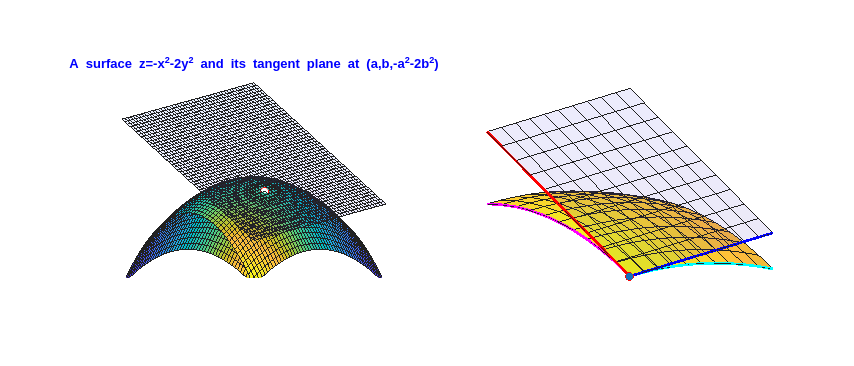

close;
l=-1.2:0.05:1.2; 
m=-1.2:0.05:1.2;
[u,v]=meshgrid(l,m);
x=u;
y=v;
z=-u.^2-2*v.^2;
C1=10*x.*y+10;

a =-0.3;
b =-0.5;
altitude = 0;
longitude = -45;

w=a^2+2*b^2-2*a*x-4*b*y;
X=[a];
Y=[b];
Z=[-a^2-2*b^2];
zx=-l.^2-2*b^2;
wx=a^2-2*b^2-2*a*l;
zy=-a^2-2*m.^2;
wy=-a^2+2*b^2-4*b*m;
A=a*ones(1,11);
B=b*ones(1,11);

na=int64(floor(20*a+25));
nb=int64(floor(20*b+25));
[xx,yy]=meshgrid(a:0.05:a+0.5,b:0.05:b+0.5);
zz=-xx.^2-2*yy.^2;
CC=10*xx.*yy+10;
ww=a^2+2*b^2-2*a*xx-4*b*yy;

figure('Position',[100 100 1400 600])

subplot(1,2,1)
surf(x,y,z,C1);
axis off
xlim([-1.3 1.3])
ylim([-1.3 1.3])
zlim([-4,4])
view(longitude,altitude)
pbaspect([1 1 1])
title('A surface z=-x^2-2y^2 and its tangent plane at (a,b,-a^2-2b^2)','Color','blue','FontSize',10)
hold on 
surf(x,y,w,'FaceAlpha',0.1);
scatter3(X,Y,Z,'filled','MarkerEdgeColor','red','MarkerFaceColor','auto');
hold off

subplot(1,2,2)
surf(xx,yy,zz,CC);
axis off
%zlim([-4,4])
view(longitude,altitude)
pbaspect([1 1 1])
%title('A surface z=-x^2-2y^2 and its tangent plane at (a,b,-a^2-2b^2)','Color','blue','FontSize',10)
hold on 
surf(xx,yy,ww,'FaceAlpha',0.1);
scatter3(X,Y,Z,'filled','MarkerEdgeColor','red','MarkerFaceColor','flat');
plot3(l(1,na:na+10),B,zx(1,na:na+10),'LineWidth',2,'Color','cyan')
plot3(l(1,na:na+10),B,wx(1,na:na+10),'LineWidth',2,'Color','blue')
plot3(A,m(1,nb:nb+10),zy(1,nb:nb+10),'LineWidth',2,'Color','magenta')
plot3(A,m(1,nb:nb+10),wy(1,nb:nb+10),'LineWidth',2,'Color','red')
hold off

### **2D Polar Coordinate System**


$$(x,y)=(r\cos\theta,r\sin\theta),
\quad
(r,\theta)=[0,\infty)\times[0,2\pi).$$


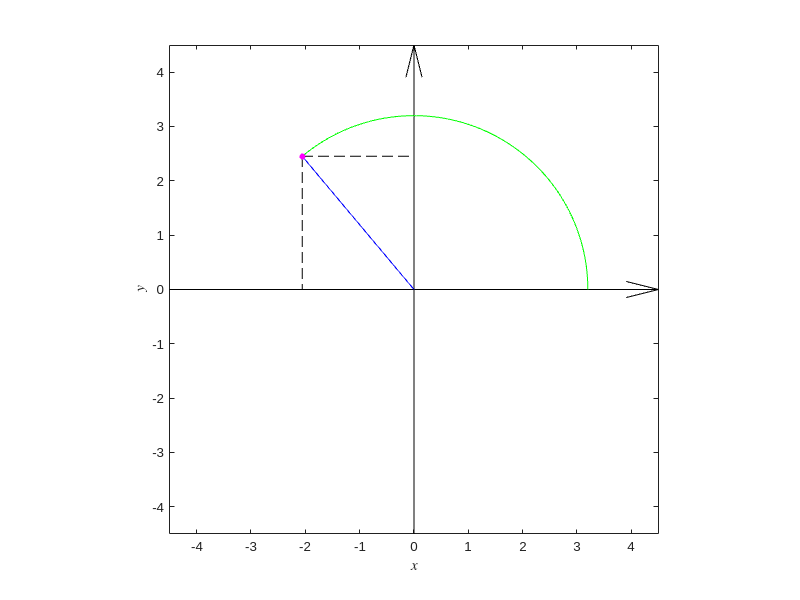

close;
r = 3.2;
theta = 130;

OX=0;
OY=0;
PX=r*cos(2*pi*theta/360);
PY=r*sin(2*pi*theta/360);
ttt=linspace(0,2*pi*theta/360,100);

figure('Position',[100 100 800 600])
quiver(-4.5,0,10,0,"black")
hold on
quiver(0,-4.5,0,10,"black")
hold on
plot(r*cos(ttt),r*sin(ttt),"green")
xlabel('$x$','Interpreter','latex')
ylabel('$y$','Interpreter','latex')
xlim([-4.5 4.5])
ylim([-4.5 4.5])
pbaspect([1 1 1])
hold on 
line([PX OX],[PY OY],'Color','blue')
hold on 
line([PX OX],[PY PY],'Color','black','LineStyle','--')
hold on 
line([PX PX],[PY OY],'Color','black','LineStyle','--')
hold on 
scatter(PX,PY,20,"magenta","filled")
hold off 

### **3D Polar Coordinate System**


$$(x,y,z)=(r\sin\theta\cos\varphi, r\sin\theta \sin\varphi,r\cos\theta),
\quad
(r,\theta,\varphi)\in[0,\infty)\times[0,\pi]\times[0,2\pi).$$


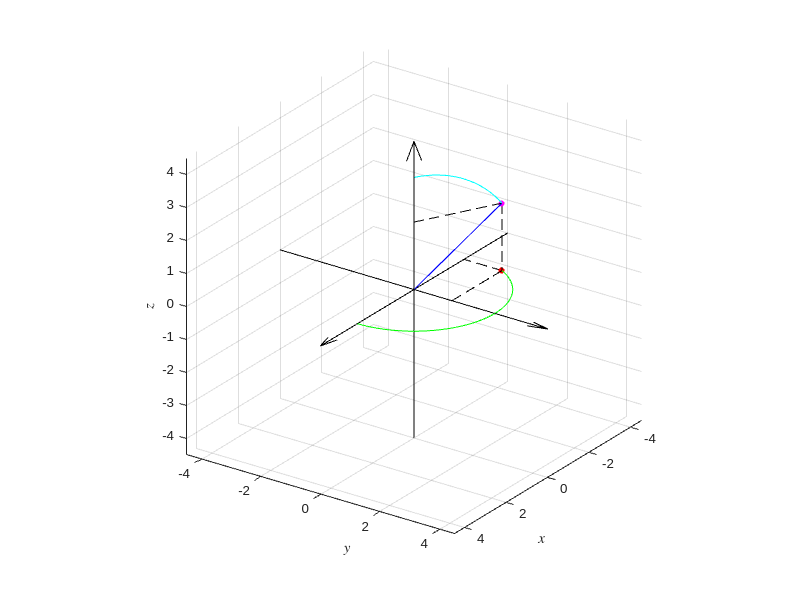

close;
close;
r = 3.4;
theta = 53;
phi = 152;

OX=0;
OY=0;
OZ=0;
PX=r*sin(pi*theta/180)*cos(2*pi*phi/360);
PY=r*sin(pi*theta/180)*sin(2*pi*phi/360);
PZ=r*cos(pi*theta/180);
ttt=linspace(0,pi*theta/180,50);
ppp=linspace(0,2*pi*phi/360,100);

figure('Position',[100 100 800 600])
quiver3(-4.5,0,0,10,0,0,"black")
hold on
quiver3(0,-4.5,0,0,10,0,"black")
hold on
quiver3(0,-0,-4.5,0,0,10,"black")
hold on
plot3(r*sin(ttt)*cos(2*pi*phi/360),r*sin(ttt)*sin(2*pi*phi/360),r*cos(ttt),"cyan")
xlabel('$x$','Interpreter','latex')
ylabel('$y$','Interpreter','latex')
zlabel('$z$','Interpreter','latex')
xlim([-4.5 4.5])
ylim([-4.5 4.5])
zlim([-4.5 4.5])
pbaspect([1 1 1])
view([125 25])
hold on
plot3(r*sin(pi*theta/180)*cos(ppp),r*sin(pi*theta/180)*sin(ppp),zeros(size(ppp)),"green")
hold on 
line([PX OX],[PY OY],[PZ OZ],'Color','blue')
hold on 
line([PX OX],[PY OY],[PZ PZ],'Color','black','LineStyle','--')
hold on 
line([PX PX],[PY PY],[PZ 0],'Color','black','LineStyle','--')
hold on 
line([PX OX],[PY PY],[0 0],'Color','black','LineStyle','--')
hold on 
line([PX PX],[PY OY],[0 0],'Color','black','LineStyle','--')
hold on 
scatter3(PX,PY,0,20,"red","filled")
hold on 
scatter3(PX,PY,PZ,20,"magenta","filled")
hold off

### **Newton's Method vs Gradient Descent**

Given a smooth funtion 

$f:\mathbb{R}^n\ni\vec{x}=[x_1,\dots,x_n]^T \mapsto f(\vec{x})\in\mathbb{R}$ and an initial point $\vec{x}_0\in\mathbb{R}^n$, 

- Newton's method formally defines a sequence $\{\vec{x}_n\}_{n=1,2,3,\dots$ by 


$$\vec{x}_{n+1}:=\vec{x}_n-\bigl(\nabla^2f(\vec{x}_n)\bigr)^{-1}{\nabla}f(\vec{x}_n), 
\quad n=1,2,3,\dots.$$


- The Gradient descent defines a sequence $\{\vec{x}_n\}_{n=1,2,3,\dotsc}$ by 


$$\vec{x}_{n+1}:=\vec{x}_n-s{\nabla}f(\vec{x}_n), \quad n=1,2,3,\dots,\quad s>0.$$


Denote the initial point by $\vec{x}_0=\bigl(a,b,f(a,b)\bigr)$.

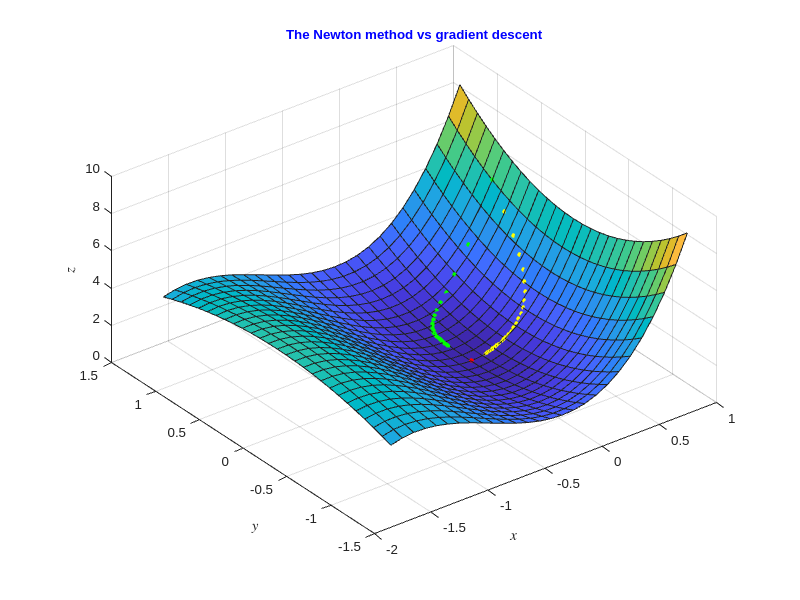

close;
s = 0.02; 
a = 0.8;
b = 0.8;
N =27;
[x,y]=meshgrid(-1.7:0.1:0.9,-1.3:0.1:1.3);
z=2*x.^3+x.*y.^2+5*x.^2+y.^2;

P=zeros(3,1);
Q=[a; b; 2*a^3+a*b^2+5*a^2*b^2];

X=zeros(3,100);
X(1,1)=a;
X(2,1)=b;
for j=1:99
    X(1,j+1)=X(1,j)-s*(6*X(1,j)^2+X(2,j)^2+10*X(1,j));
    X(2,j+1)=X(2,j)-s*(2*X(1,j)*X(2,j)+2*X(2,j));
end
X(3,:)=2*X(1,:).^3+X(1,:).*X(2,:).^2+5*X(1,:).^2+X(2,:).^2;

Y=zeros(3,100);
Y(1,1)=a;
Y(2,1)=b;
for j=1:99
    D=12*Y(1,j)^2-2*Y(2,j)^2+22*Y(1,j)+10;
    Y(1,j+1)=(12*Y(1,j)^3-2*Y(1,j)*Y(2,j)^2+21*Y(1,j)^2+9*Y(1,j))/D;
    Y(2,j+1)=Y(2,j)*(12*Y(1,j)^2-Y(2,j)^2+17*Y(1,j)+5)/D;
end
Y(3,:)=2*Y(1,:).^3+Y(1,:).*Y(2,:).^2+5*Y(1,:).^2+Y(2,:).^2;

figure('Position',[100 100 800 600])
r=surf(x,y,z);
pbaspect([2 2 1])
title('The Newton method vs gradient descent','Color','blue','FontSize',10)
xlabel('$x$','Interpreter','latex')
ylabel('$y$','Interpreter','latex')
zlabel('$z$','Interpreter','latex')
hold on
newcolors = [1 0 0; 
             1 1 0;
             0 1 0;
             1 0 1];
colororder(newcolors)        
plot3(P(1,:),P(2,:),P(3,:),'.',Y(1,1:N),Y(2,1:N),Y(3,1:N),'.', ...
    X(1,1:N),X(2,1:N),X(3,1:N),'.',Q(1,:),Q(2,:),Q(3,:),'.', 'MarkerSize',10)
hold off

### **Riemann Sum**

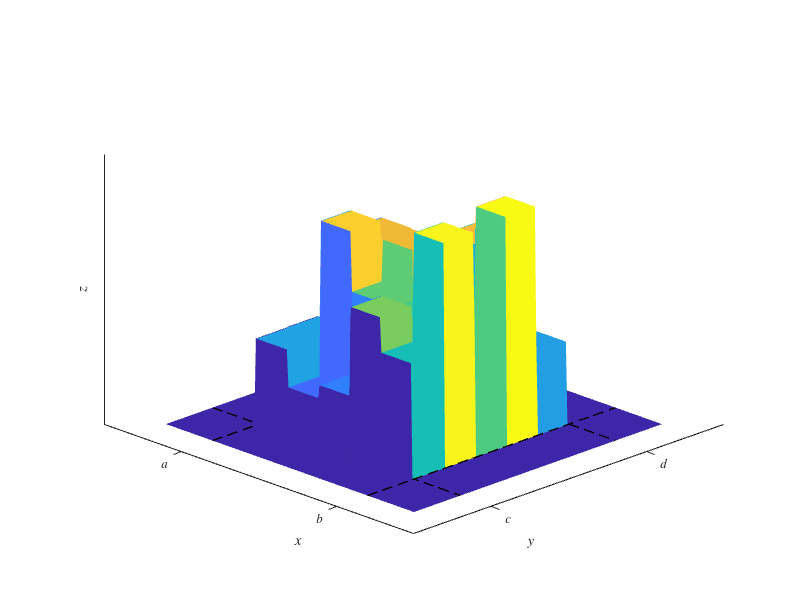

close;
n8 = 5;
N8 = 100;

x8 = linspace(-0.3, 1.3, N8+61);
y8 = linspace(-0.3, 1.3, N8+61);

R8 = rand(n8, n8);
z8 = zeros(N8+61, N8+61);

z8(30,30) = R8(1,1);
for k = 1:N8
    z8(30, k+30)   = R8(1, ceil(k/20));
    z8(k+30, 30)   = R8(ceil(k/20), 1);
    for l = 1:N8
        z8(k+30, l+30) = R8(ceil(k/20), ceil(l/20));
    end
end

% --- plot (roughly same appearance as Julia) ---
figure('Position',[100 100 800 600])
surf(x8, y8, z8.', 'EdgeColor','none');             
zlim([0 1.1])
grid off
view(45,30)

colormap(parula)                                  

ax = gca;
ax.TickLabelInterpreter = 'latex';
ax.XTick = [0 1];   ax.XTickLabel = {'$a$','$b$'};
ax.YTick = [0 1];   ax.YTickLabel = {'$c$','$d$'};
ax.ZTick = [];

xlabel('$x$','Interpreter','latex')
ylabel('$y$','Interpreter','latex')
zlabel('$z$','Interpreter','latex')

hold on
plot3([-0.3 1.3],[0 0],[0 0],'k--','LineWidth',1)
plot3([1 1.3],[1 1],[0 0],'k--','LineWidth',1)
plot3([1 1],[-0.3 1.3],[0 0],'k--','LineWidth',1)
plot3([0 0],[-0.3 0],[0 0],'k--','LineWidth',1)
hold off

### Convergence of Riemann Sum

Given a continuous function $f(x,y)$ on $I=[a,b]\times[c,d]$. Theoretically $f(x,y)$ is Riemann integrable. 

We have a division of $I$ splitting $[a,b]$ and $[c,d]$ into $n$-equal parts respectively:


$$I_{jk}=\left[a+\frac{(b-a)(j-1)}{n},a+\frac{(b-a)j}{n}\right]\times\left[c+\frac{(d-c)(k-1)}{n},c+\frac{(d-c)k}{n}\right].$$


Pick up arbitrary $(x_{jk},y_{jk}) \in I_{jk}$. Define a Riemann sum $R_n$ of $f(x,y)$ by 


$$R_n
=
\sum_{j=1}^n\sum_{k=1}^n
f(x_{jk},y_{jk}) |
I_{jk}|
=
\frac{(b-a)(d-c)}{n^2}
\sum_{j=1}^n\sum_{k=1}^nf(x_{jk},y_{jk}).$$


Then 


$$R_n \rightarrow \int\int_{I}f(x,y)dxdy \quad (n \rightarrow \infty).$$


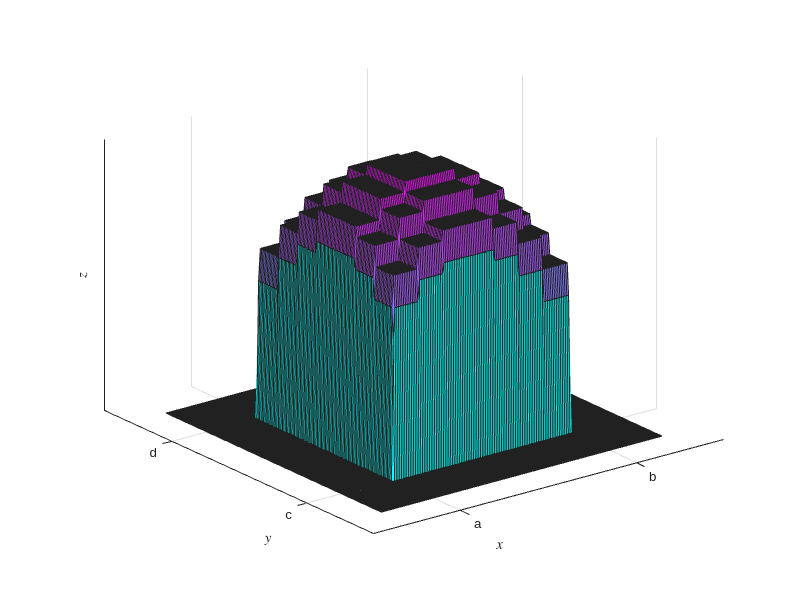

close;
n  = 7;

N9=100;
R9=zeros(N9,N9);
for j=1:N9
	for k=1:N9
		R9(j,k)=1-(1/2-j/N9)^2-(1/2-k/N9)^2;
	end
end

x9 = linspace(-0.3, 1.3, N9+61);
y9 = linspace(-0.3, 1.3, N9+61);
z9=zeros(N9+61,N9+61);
z9(30,30)=R9(1,1);
for k=1:N9
    z9(30,k+30)=R9(1,int64(ceil(ceil(n*k/100)*N9/n)));
	z9(k+30,30)=R9(int64(ceil(ceil(n*k/100)*N9/n)),1);
	for l=1:N9
		z9(k+30,l+30)=R9(int64(ceil(ceil(n*k/N9)*N9/n)),int64(ceil(ceil(n*l/N9)*N9/n)));
	end
end

figure('Position',[100 100 800 600])
surf(x9,y9,z9)
colormap(cool)
xlabel('$x$','Interpreter','latex')
ylabel('$y$','Interpreter','latex')
zlabel('$z$','Interpreter','latex')
xticks([0 1])
xticklabels({'a','b'})
yticks([0 1])
yticklabels({'c','d'})
zticks([])